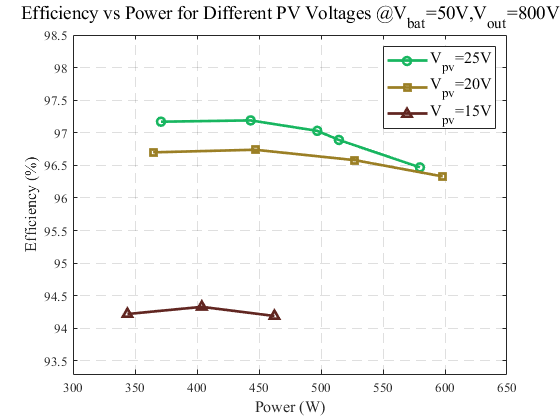

% 定义光伏端口的功率和效率数据
% 对应25V的光伏端口数据
power_25V = [579.756, 514.424, 496.956, 443.251, 370.932];
efficiency_25V = [96.47, 96.89, 97.03, 97.19, 97.17];

% 对应20V的光伏端口数据
power_20V = [598.216, 527.41, 446.833, 364.668];
efficiency_20V = [96.33, 96.58, 96.74, 96.7];

% 对应15V的光伏端口数据
power_15V = [462.454, 403.854, 343.895];
efficiency_15V = [94.19, 94.33, 94.22];

% 创建一个新的图形窗口
figure;

% 绘制25V光伏端口数据
plot(power_25V, efficiency_25V, '-o', 'DisplayName', 'V_{pv}=25V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [24/256, 183/256, 96/256]); % rgb(24,183,96) #18b760 ；[0.2, 0.4, 1]); % 使用更柔和的蓝色 [0.1, 0.8, 0.3]); % 使用更柔和的绿色 [1, 0.3, 0.3]); % 使用更柔和的红色

hold on;

% 绘制20V光伏端口数据
plot(power_20V, efficiency_20V, '-s', 'DisplayName', 'V_{pv}=20V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [156/256, 127/256, 37/256]); %  rgb(156,127,37) #9c7f25;实验波形绿：'Color', [25/256, 215/256, 25/256]

% 绘制15V光伏端口数据
plot(power_15V, efficiency_15V, '-^', 'DisplayName', 'V_{pv}=15V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [97/256, 38/256, 33/256]); % rgb(97,38,33) #612621

% 设置坐标轴标签
xlabel('Power (W)', 'FontSize', 12, 'FontName', 'Times New Roman');
ylabel('Efficiency (%)', 'FontSize', 12, 'FontName', 'Times New Roman');

% 设置标题
title('Efficiency vs Power for Different PV Voltages @V_{bat}=50V,V_{out}=800V', 'FontSize', 14, 'FontName', 'Times New Roman');

% 设置坐标轴范围
xlim([300, 650]); % 将横坐标范围从300开始
ylim([93.3, 98.5]); % 根据效率范围，设定纵坐标范围

% 添加网格
grid on;
set(gca, 'GridLineStyle', '--'); % 设置网格线为虚线

% 添加图例
legend('Location', 'northeast', 'FontSize', 12, 'FontName', 'Times New Roman');

% 设置字体为新罗马字体
set(gca, 'FontName', 'Times New Roman');

% 显示图形
hold off;